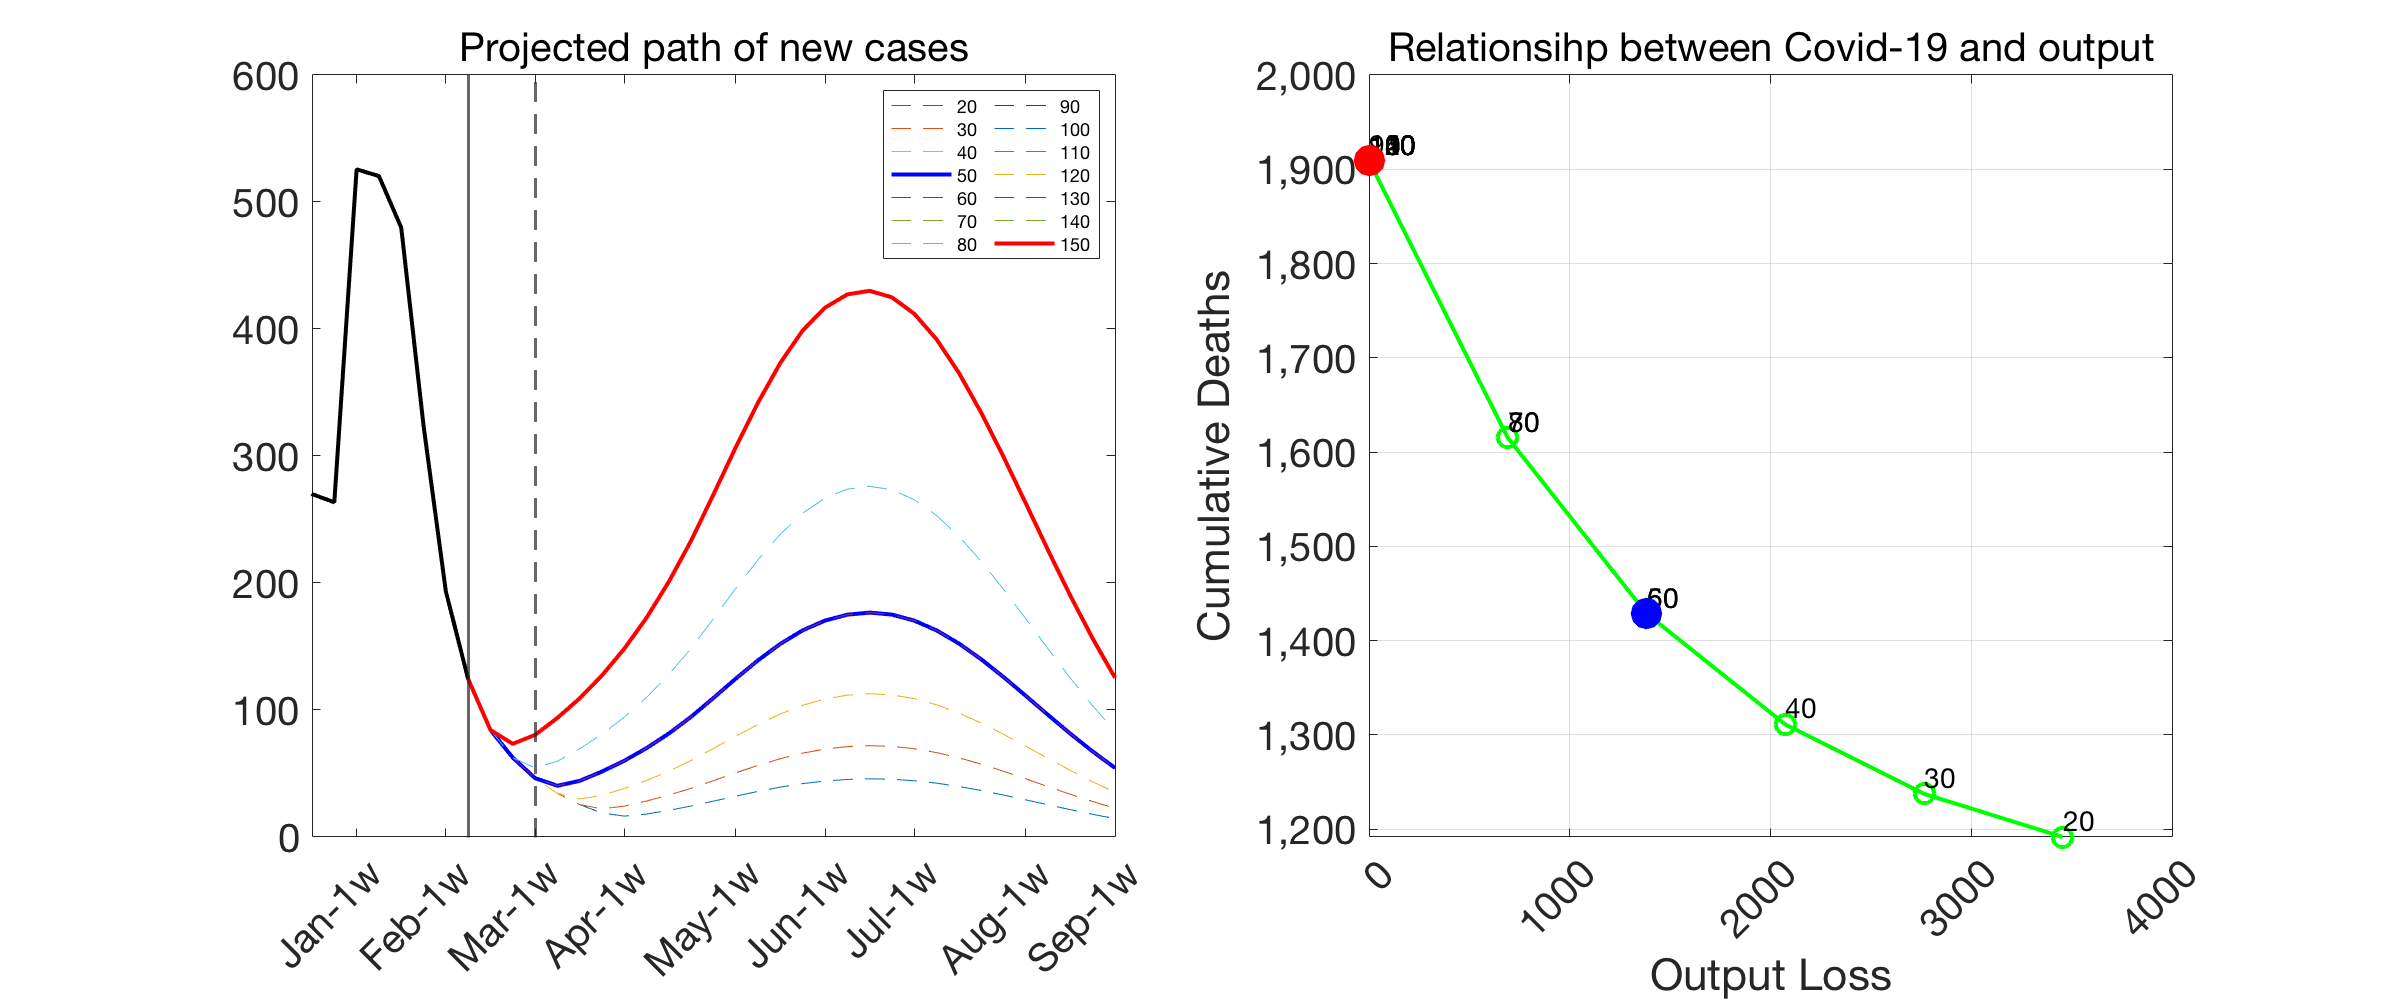

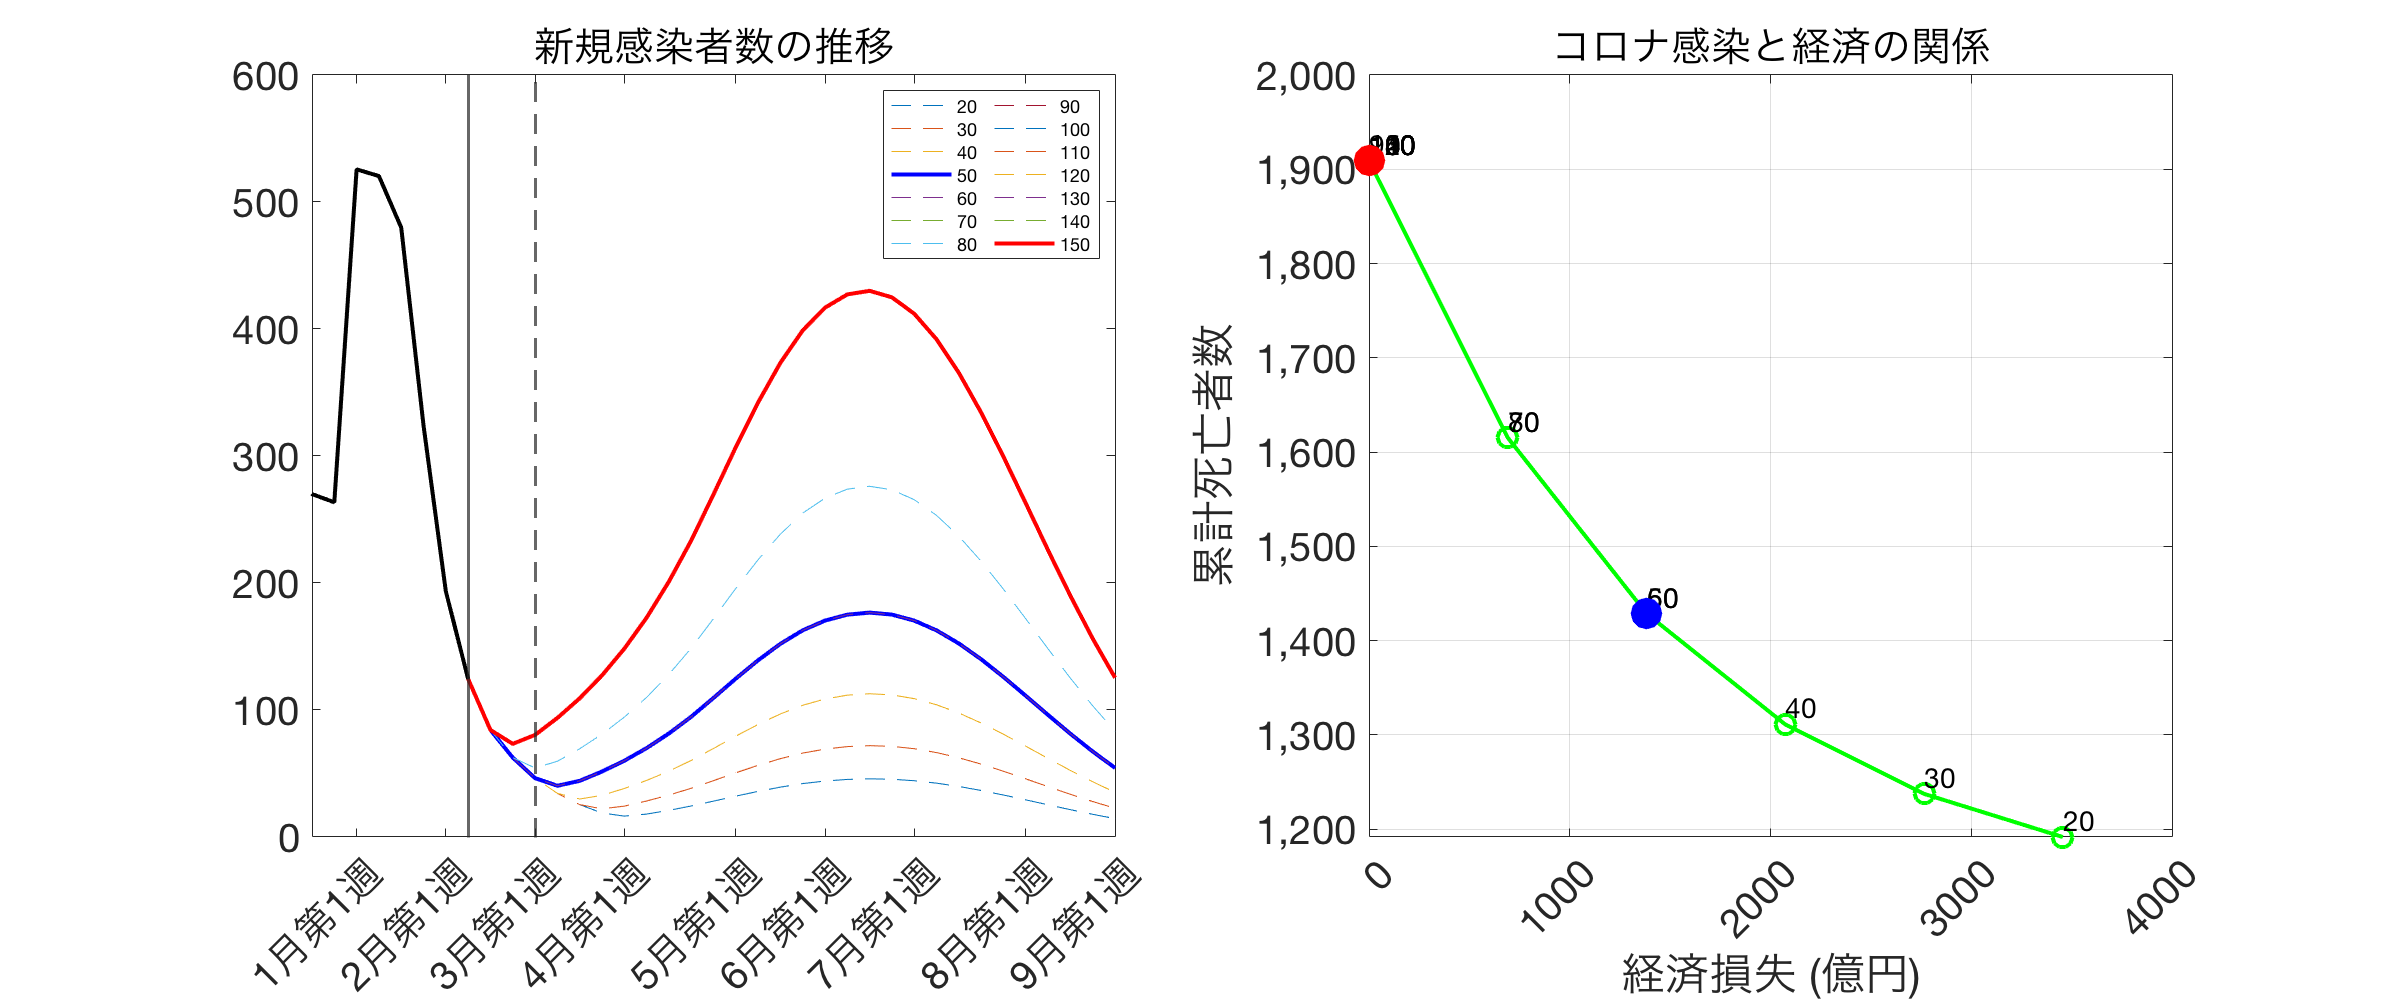

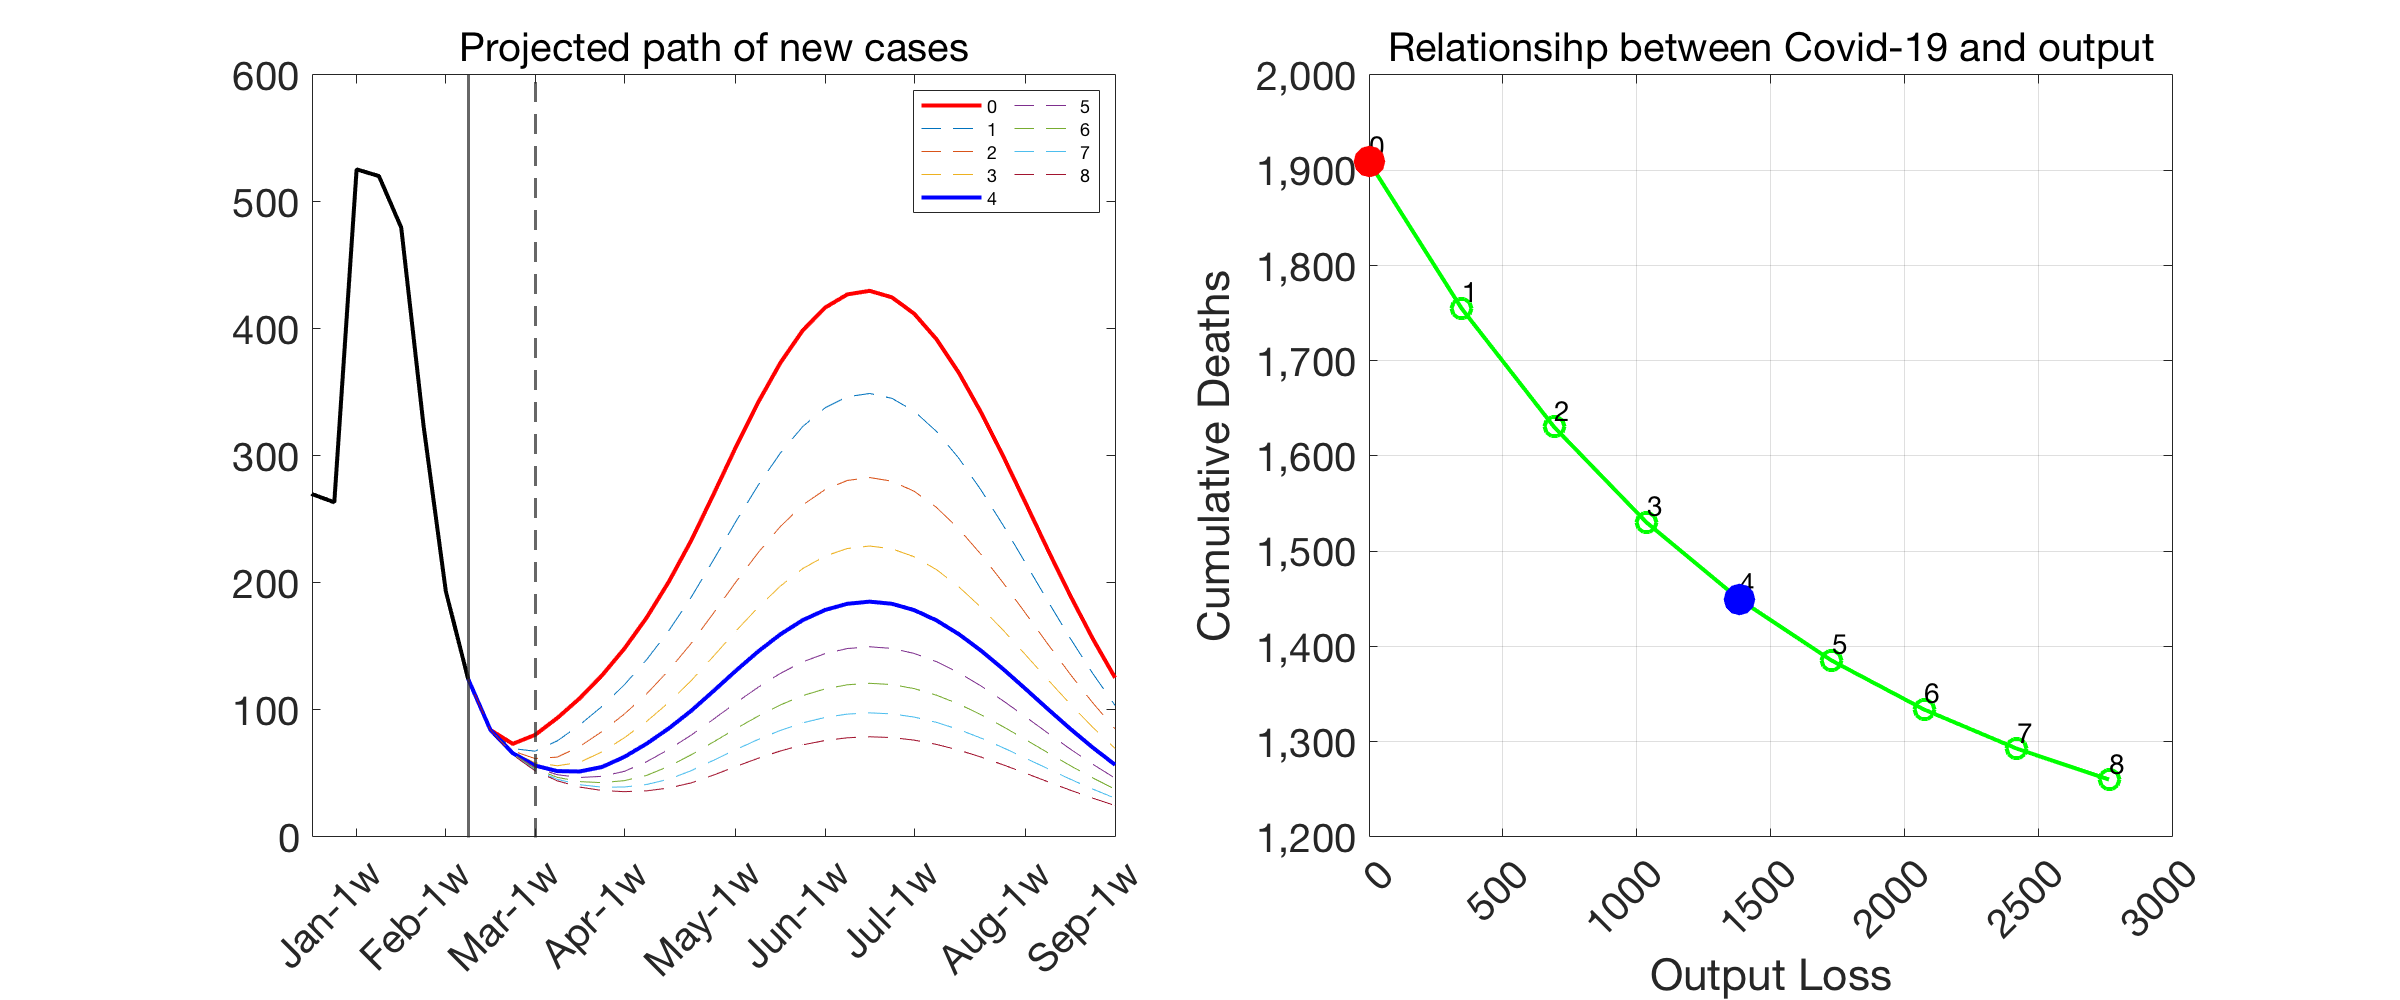

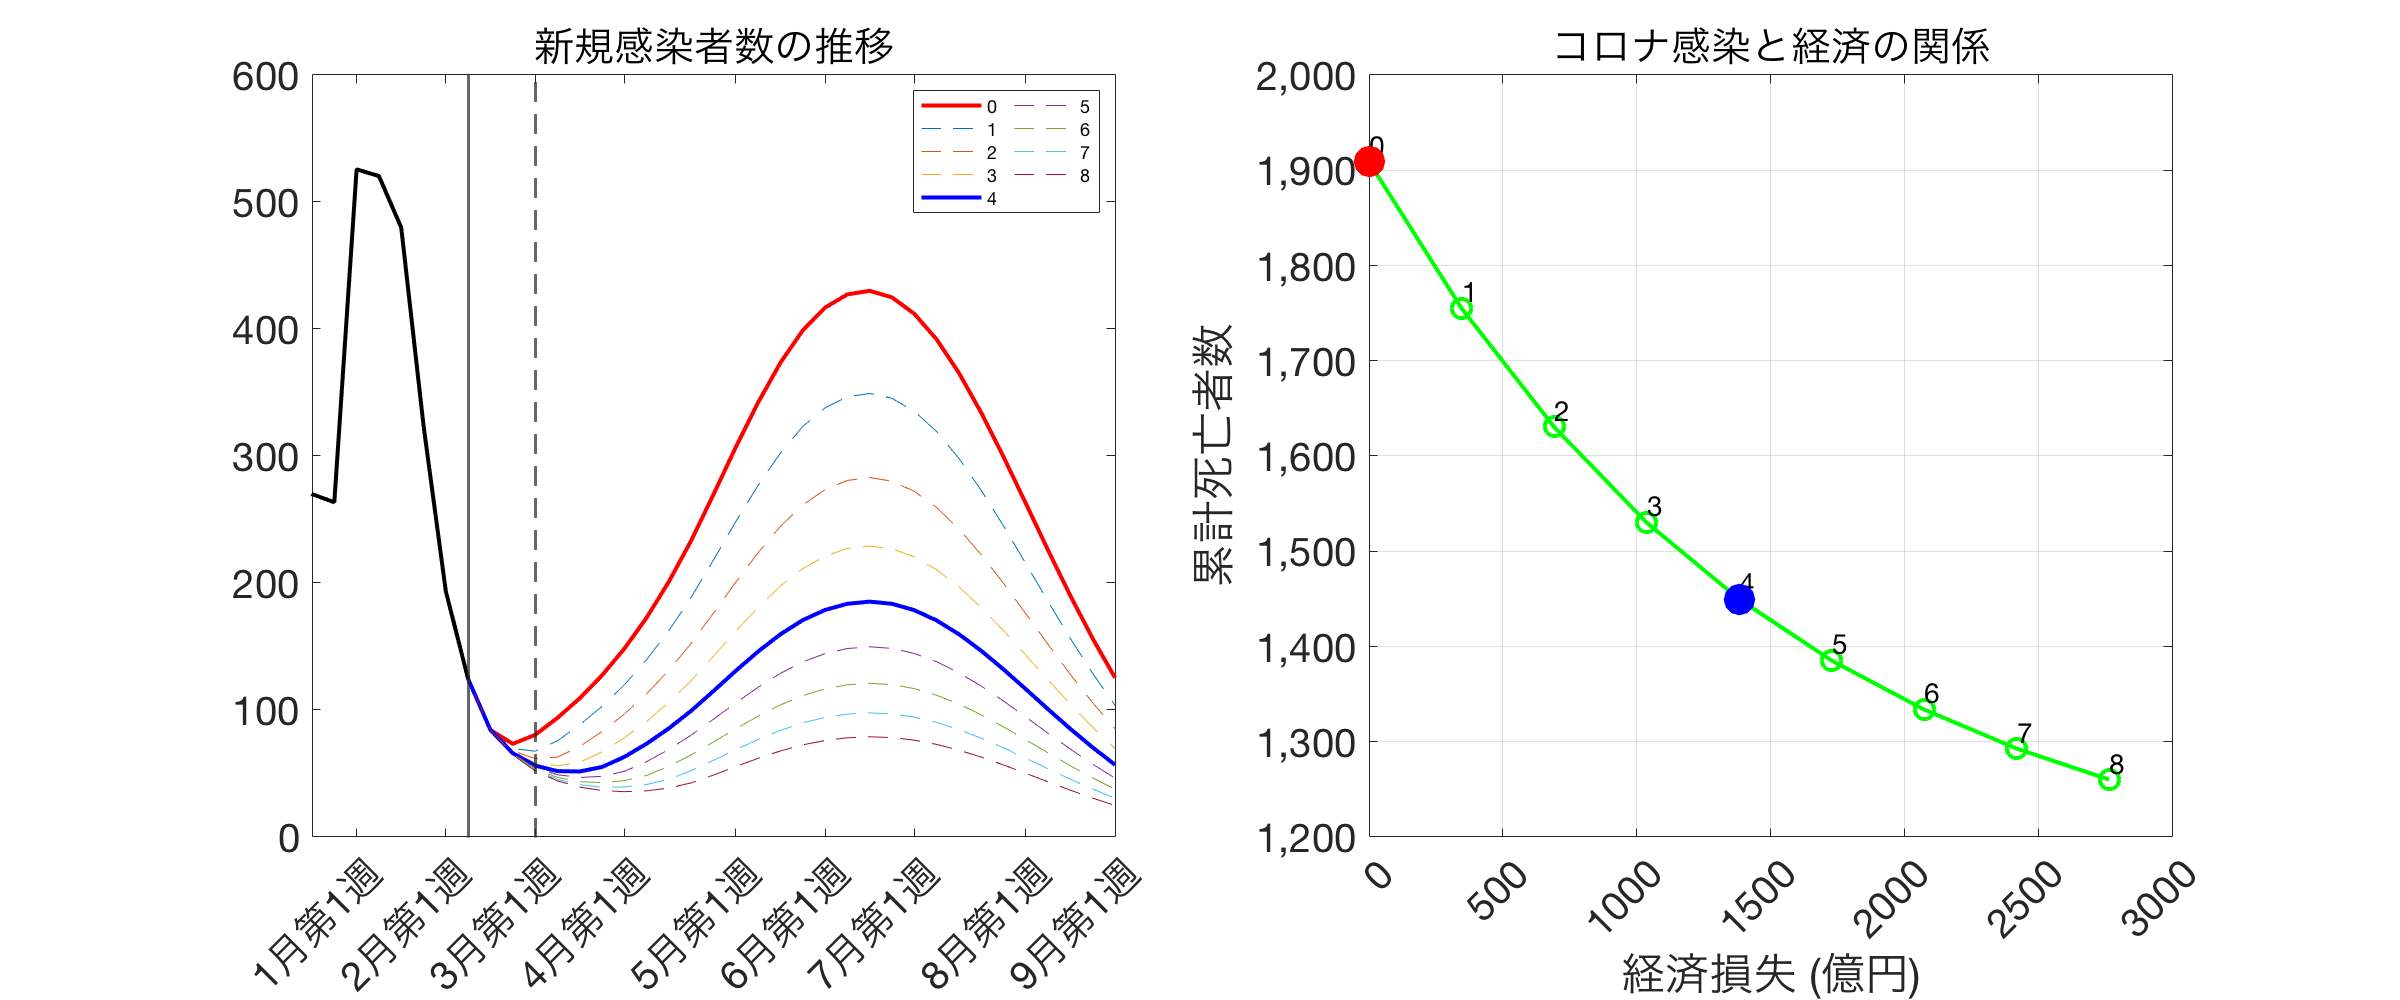

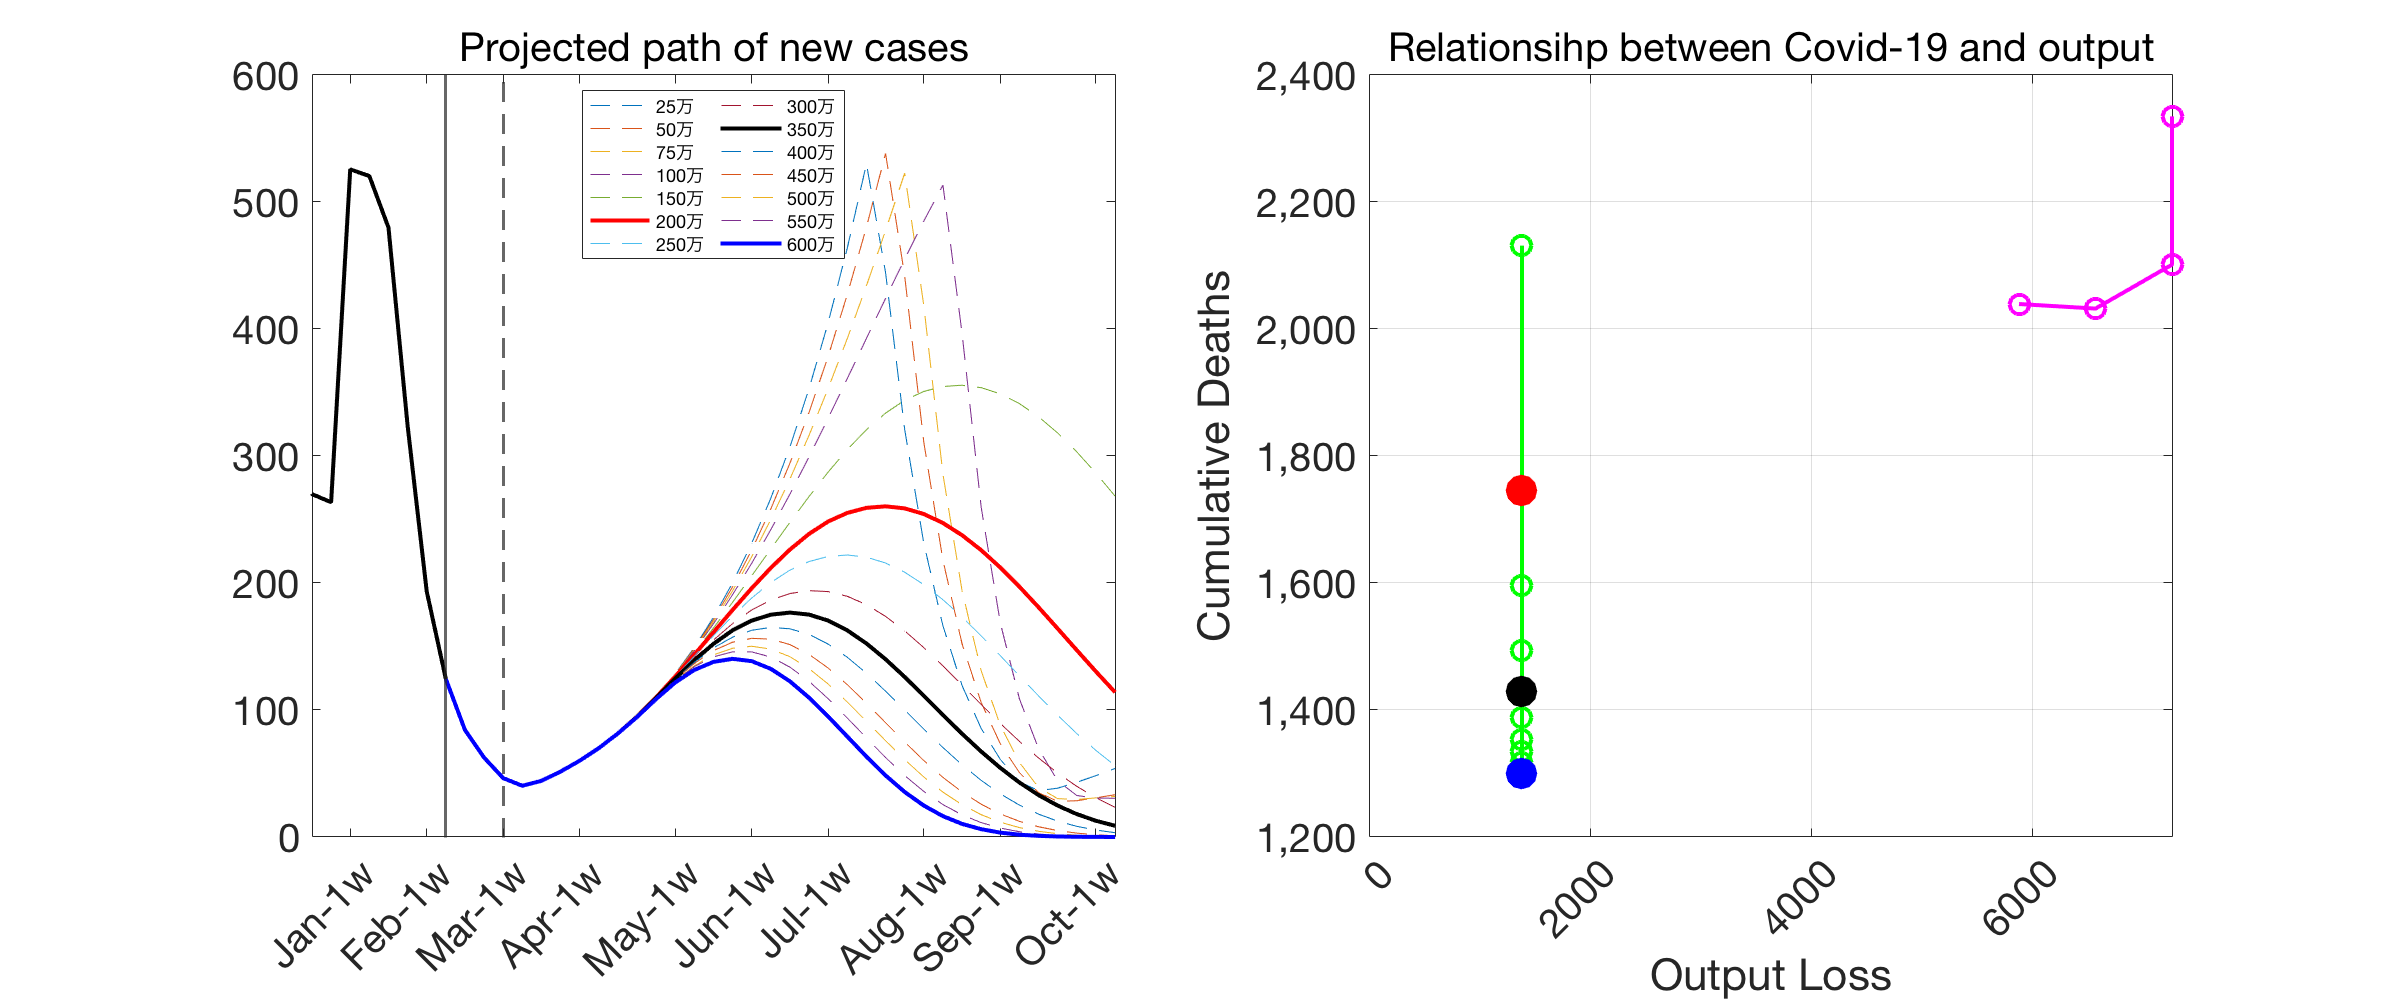

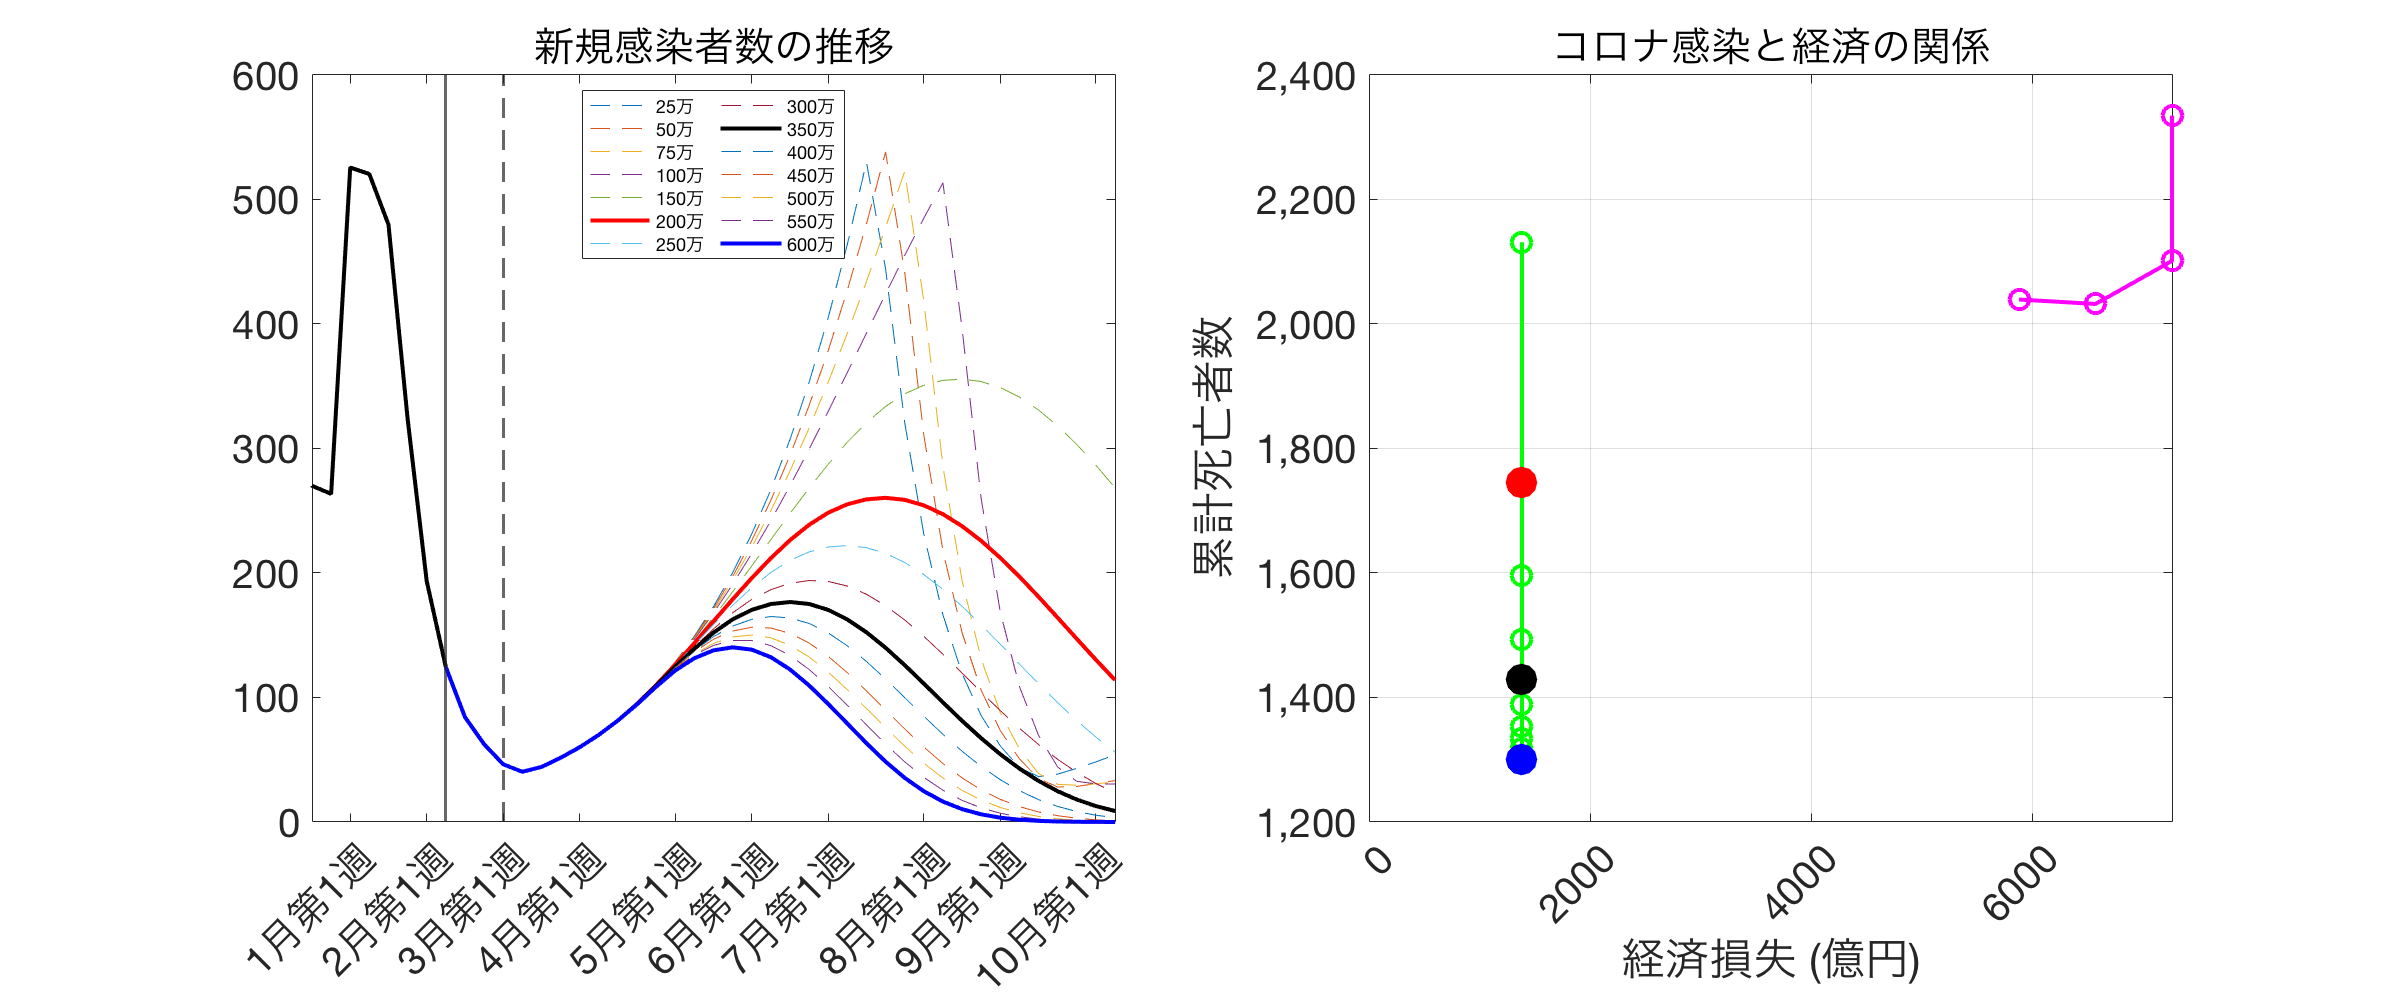

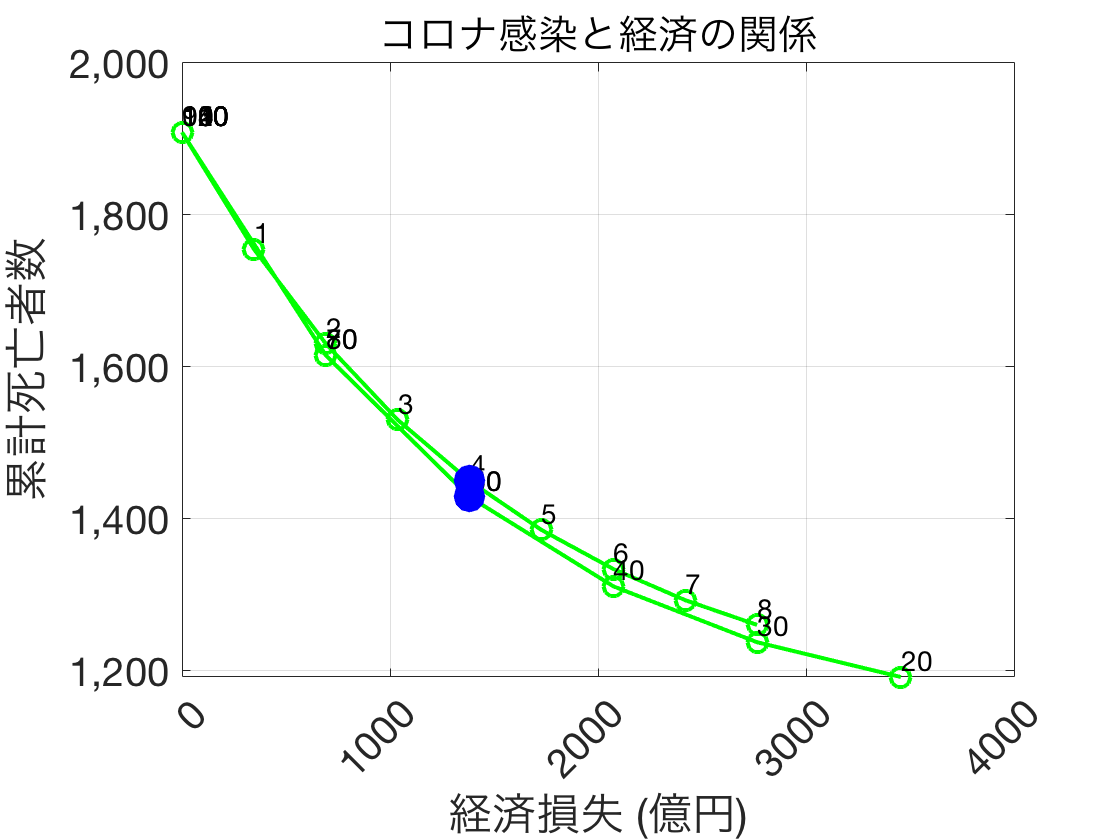

% This m-file executes simulation and generates figures for the
% analysis of the state of emergency placed in Tokyo in the paper
% "Covid-19 and Output in Japan" by Daisuke Fujii and Taisuke
% Nakata

clear variables
close all
home = '/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/';
cd(home);
%====================== Program parameter values ======================%
figure_save = 1;    % 0 = figures won't be saved, 1 = they will be saved
data_save = 0;      % save back data
iPC=0;              % 1 if PC, 0 if Mac (or "home=pwd" does not work)
% in the "Figure" folder
fs = 16;            % common font size for many figures
%======================================================================%

%====================== Model parameter values ======================%
pref = 'Osaka';        % prefecture to be analyzed
% GDP_vector = [106,40,36,24,22]*100;
prefGDP = 40;
gamma = 7/5;          % recovery rate from Covid
k = 2;                 % exponent of (1-h*alpha)
hconstant = 1;         % 0 = without intercept, 1 = with intercept for h regression
SimPeriod = 52;        % simulation period in weeks
medical_start_date = "Mar-18";
elderly_start_date = "Apr-01";
% VacStartDate = "Apr-01";             % time until the start of vaccination process
% 
% VacDuration = 12;       % time until vaccination pace reaches its steady pace
RetroPeriod = 17;      % retroactive periods used to estimate gamma and delta
%====================================================================%

%--- Import data ---%
% Covid data are recorded at weekly frequencies (Mon-Sun)
% The first week start on January 20 (Mon), 2020
if iPC==1
    covid = importdata([home '\Covid_weekly.csv']);  % Import weekly Covid data by prefecture
else
    covid = importdata([home 'Covid_weekly.csv']);  % Import weekly Covid data by prefecture
end
Data = covid.data(strcmp(covid.textdata(2:end,1),pref),:);
% Columns: 1 = date, 2 = new positive, 3 = death, 4 = mobility, 5 = GDP, 6 = population
dateD = Data(:,1) + 21916;
N = Data(:,2);
dD = Data(:,3);
M = Data(:,4);
GDP = Data(:,5);
POP = Data(:,6);
Tdata= size(Data,1);    % Data period in weeks
POP0 = POP(1);          % initial population
ps = POP0/125710000;    % population share
xtick1 = 1:13:Tdata;
dateJP = string(datetime(dateD,'ConvertFrom','excel','Format','M月dd日'));
dateEN = string(datetime(dateD,'ConvertFrom','excel','Format','MMM-dd'));
Month = string(datetime(dateD,'ConvertFrom','excel','Format','MMM-yy'));
SimDate = dateD(end)+7:7:dateD(end)+7*SimPeriod;
SimDateEN = string(datetime(SimDate,'ConvertFrom','excel','Format','MMM-dd'));
%--- Create Month-Week labels ---%
dateP = dateD(end)+7:7:dateD(end)+7*(SimPeriod+1);
date = [dateD;dateP'];
MonthNumber = month(datetime(date,'ConvertFrom','excel'));
WeekNumber = zeros(length(MonthNumber),1);
WeekNumber(1:2) = [3;4];
for i = 3:length(WeekNumber)
    if MonthNumber(i)~=MonthNumber(i-1)
        WeekNumber(i) = 1;
    else
        WeekNumber(i) = WeekNumber(i-1) + 1;
    end
end
MonthWeekJP = strings([length(MonthNumber),1]);
MonthWeekEN = strings([length(MonthNumber),1]);
for i = 1:length(MonthNumber)
    MonthWeekJP(i) = [char(string(MonthNumber(i))) '月第' char(string((WeekNumber(i)))) '週'];
    MonthWeekEN(i) = [char(string(datetime(date(i),'ConvertFrom','excel','Format','MMM'))) '-' char(string((WeekNumber(i)))) 'w'];
end

M = 1+0.01*M;
TdataGDP = Tdata-sum(isnan(GDP));
RetroH = TdataGDP-4;
VacStart = find(SimDateEN == "Apr-01");
medical_start = find(SimDateEN == medical_start_date);
elderly_start = find(SimDateEN == elderly_start_date);
End2020 = find(dateEN == "Jan-07");


%--- Constructing the reference level of output ---%
potentialGDP = zeros(52*3,1);
potentialGDP(1) = (100/(1.0122))*(1.0063^(1/12));
for i = 2:length(potentialGDP)
    if i <= 13
        potentialGDP(i) = potentialGDP(i-1)*(1.0063^(1/52));
    elseif i <= 52
        potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
    elseif i <= 104
        potentialGDP(i) = potentialGDP(i-1)*(1.0024^(1/52));
    elseif i <= 156
        potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
    end
end
% gapGDP = zeros(length(potentialGDP),1);
% gapGDP(1) = 0.0166;
% for i = 2:length(gapGDP)
%     gapGDP(i) = gapGDP(i-1)*(0.975^(12/52));
% end
referenceGDP = potentialGDP.*(1+0.0166);
referenceGDP(1:2) = [];


%--- Impute alpha (regress alpha on M)---%
Malt=M;
Malt(50)=0.5*(Malt(49)+Malt(51));
alpha = (1 - GDP(1:TdataGDP)./referenceGDP(1:TdataGDP));   % output loss in percentage
X = M(TdataGDP-17:TdataGDP);
Y = alpha(TdataGDP-17:TdataGDP);
XC = [ones(length(X),1), X];
s = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
reg = XC*s;
r = Y - reg;
SSE = sum(r.^2);
eps_p = zeros(Tdata-TdataGDP,1);
eps_p(1) = r(end);
for i = 1:Tdata-TdataGDP-1
    eps_p(i+1) = 1*eps_p(i);
end
alpha_pred = s(1)+s(2)*Malt(TdataGDP+1:Tdata)+eps_p;

alpha = [alpha;alpha_pred];


%--- Regress mobility on alpha to estimate the elasticity h ---%
Y = M(4:TdataGDP);
X = alpha(4:TdataGDP);
if hconstant == 0
    Y = Y - 1;
    h_all = (X'*X)\X'*Y;              % OLS estimate of h
    reg = X*h_all;
    r = Y - reg;                % r is the residuals, which is the observed minus fitted values
    SSE = sum(r.^2);            % SSE is the sum of squared errors
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_all_se=sqrt(MSE/sum(X.^2));   % standard error of h
elseif hconstant == 1
    XC = [ones(length(X),1), X];
    h_all = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*h_all;
    r = Y - reg;
    SSE = sum(r.^2);
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_all_se = zeros(2,1);
    h_all_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
    h_all_se(2)=sqrt(MSE/sum(XC(:,2).^2));
end

Y = M(TdataGDP-RetroH:TdataGDP);
X = alpha(TdataGDP-RetroH:TdataGDP);
if hconstant == 0
    Y = Y - 1;
    h = (X'*X)\X'*Y;              % OLS estimate of h
    reg = X*h;
    r = Y - reg;                % r is the residuals, which is the observed minus fitted values
    SSE = sum(r.^2);            % SSE is the sum of squared errors
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_se=sqrt(MSE/sum(X.^2));   % standard error of h
elseif hconstant == 1
    XC = [ones(length(X),1), X];
    h = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*h;
    r = Y - reg;
    SSE = sum(r.^2);
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_se = zeros(2,1);
    h_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
    h_se(2)=sqrt(MSE/sum(XC(:,2).^2));
end

%--- Compute the history of S, I, R, D in the data period ---%
S = zeros(Tdata+1,1);
I = zeros(Tdata+1,1);
R = zeros(Tdata+1,1);
D = zeros(Tdata+1,1);
S(1)=POP0;
for i = 1:Tdata
    S(i+1)=S(i)-N(i);
    I(i+1)=I(i)+N(i)-gamma*I(i)-dD(i);
    R(i+1)=R(i)+gamma*I(i);
    D(i+1)=D(i)+dD(i);
    if i > TdataGDP
        GDP(i) = referenceGDP(i)*(1-alpha(i));
    end
end

%--- Compute the history of time-varying parameters ---%

delta = (D(2:Tdata+1)-D(1:Tdata))./I(1:Tdata);                              % death rate
beta_tilde = -POP0*((S(2:Tdata+1)-S(1:Tdata))./(S(1:Tdata).*I(1:Tdata)));   % overall infection rate
ERN = (S(1:end-1)/POP0).*beta_tilde./(gamma+delta);                                        % effective reproduction number
if hconstant == 0
    beta = beta_tilde./(1+h_all*alpha).^k;                                      % raw infection rate
elseif hconstant == 1
    %     beta = beta_tilde./(h(1)+h(2)*alpha).^k;
    beta = beta_tilde./(1+(h_all(2)/h_all(1))*alpha).^k;
end


%%%%%%%%%%%%%%%%% Projection starts here %%%%%%%%%%%%%%%%%
alpha_off = mean(alpha(Month == "Sep-20" | Month == "Oct-20"  | Month == "Nov-20")); % output loss without the state of emergency
InitialValues = [S(end),I(end),R(end),D(end)];

%--- Construct time series of parameters ---%
gammaT = gamma*ones(SimPeriod,1);
beta_sample = beta(end-RetroPeriod+1:end);
betaT = mean(beta_sample)*ones(SimPeriod,1);
delta_sample = delta(end-RetroPeriod+1:end);
delta_average = mean(delta_sample);

pace = ps*3500000;
medical = ps*3700000*0.8;
elderly = ps*36000000*0.8;
ordinary = (125710000-36000000-3700000)*ps*0.8;
elderly_total = ps*36000000;

[V,deltaT,VT,real_pace] = vaccine_path(pace,SimPeriod,medical,elderly,ordinary,medical_start,elderly_start,4,0.9,delta_average,elderly_total);

% VacPace = (POP0/125710000)*0.9*(3000000/2);  % number of vaccinations per week
% V = zeros(SimPeriod,1);
% V(VacStart-1:VacStart+VacDuration-1) = 0:VacPace/VacDuration:VacPace;
% V(VacStart+VacDuration:end) = VacPace;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Projection parameters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
th_on =500*7;         % threshold to place the state of emergency (daily new infected persons in Tokyo = 1750)
ERN_on = 0.82;
altA = (((ERN_on*(POP0/S(end))*((gammaT(1)+deltaT(1))/betaT(1))).^(1/k))-1)*(h(1)/h(2));
% ERNCheck = (S(end)/POP0).*(((1+(h(2)/h(1))*altA).^k).*betaT(1))./(gammaT(1)+deltaT(1));
DMat = nan(3,40);
AlphaMat = nan(3,40);
AlphaPath = nan(SimPeriod,40,3);
NPath = nan(SimPeriod,40,3);

%---- 1. Different thresholds to lift the state of emergency ---%
TL = 20:10:150;   
TL_index = [150,50];
for i = 1:length(TL)
    [DMat(1,i),AlphaMat(1,i),AlphaPath(:,i,1),SimData,NPath(:,i,1)] = Covid_projection_control_gradual(InitialValues,altA,alpha_off,th_on,TL(i)*7,betaT,gammaT,deltaT,V,h_all,k,POP0,hconstant,1);      
end
%---------------------------------------------------------------%

%---- 2. Different durations for economic recovery ---%
DR = 0:8;
DR_index = [0,4];
for i = 1:length(DR)
    [DMat(2,i),AlphaMat(2,i),AlphaPath(:,i,2),SimData,NPath(:,i,2)] = Covid_projection_control_gradual(InitialValues,altA,alpha_off,th_on,150*7,betaT,gammaT,deltaT,V,h_all,k,POP0,hconstant,1+DR(i));      
end
%-----------------------------------------------------%

%------------ 3. Different vaccine pace -------------%
VP = [25,50,75,100:50:600];
VP_index = [200,600,350];
for i = 1:length(VP)
    [V,deltaT,VT,real_pace] = vaccine_path(ps*VP(i)*10000,SimPeriod,medical,elderly,ordinary,medical_start,elderly_start,4,0.9,delta_average,elderly_total);
    [DMat(3,i),AlphaMat(3,i),AlphaPath(:,i,3),SimData,NPath(:,i,3)] = Covid_projection_control_gradual(InitialValues,altA,alpha_off,th_on,50*7,betaT,gammaT,deltaT,V,h_all,k,POP0,hconstant,1);
end
%-----------------------------------------------------%



minAlpha = min(AlphaMat,[],'all');

for y = 1:3
    if y == 1
        TH = TL;
        TH_index = TL_index;
    elseif y == 2
        TH = DR;
        TH_index = DR_index;
    elseif y == 3
        TH = VP;
        TH_index = VP_index;
    end
    AlphaM = AlphaMat(y,:);
    AlphaM = AlphaM(~isnan(AlphaM));
    DM = DMat(y,:);
    DM = DM(~isnan(DM));
    AlphaM = (AlphaM - minAlpha)*prefGDP*10000;
    %--- Record how many times on and off are triggered ---%
    waves = zeros(1,length(TH));
    for i = 1:length(TH)
        svec = zeros(SimPeriod-1,1);
        for t = 1:SimPeriod-1
            svec(t) = AlphaPath(t+1,i,y)-AlphaPath(t,i,y);
        end
        waves(i) = sum(svec>0);
    end
    
    if y == 1
        ATL = AlphaM(waves==0);
        DTL = DM(waves==0);
        THTL = TH(waves==0);
        ATLblue = AlphaM(TH==TH_index(2));
        DTLblue = DM(TH==TH_index(2));
    elseif y == 2
        ADR = AlphaM(waves==0);
        DDR = DM(waves==0);
        THDR = TH(waves==0);
        ADRblue = AlphaM(TH==TH_index(2));
        DDRblue = DM(TH==TH_index(2));
    end
    
    for l = 1:2
        if l == 1
            figure(11+y)
        elseif l == 2
            figure((11+y)*10+1)
        end
        set(gcf,'Position',[100,100,1200,500])
        %set(gcf,'Position',[100,100,1200,1000])
        subplot(1,2,1)
        if y == 1 || y == 2
            for i = 1:length(TH)
                if TH(i) == TH_index(1)
                    plot([N;NPath(:,i,y)]/7,'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                elseif TH(i) == TH_index(2)
                    plot([N;NPath(:,i,y)]/7,'-b','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                else
                    plot([N;NPath(:,i,y)]/7,'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)))
                end
                hold on
            end
        elseif y == 3
            if l == 1
                for i = 1:length(TH)
                    if TH(i) == TH_index(1)
                        plot([N;NPath(:,i,y)]/7,'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                    elseif TH(i) == TH_index(2)
                        plot([N;NPath(:,i,y)]/7,'-b','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                    elseif TH(i) == TH_index(3)
                        plot([N;NPath(:,i,y)]/7,'-k','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
                    else
                        plot([N;NPath(:,i,y)]/7,'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)))
                    end
                    hold on
                end
            elseif l == 2
                for i = 1:length(TH)
                    if TH(i) == TH_index(1)
                        plot([N;NPath(:,i,y)]/7,'-r','LineWidth',2,'DisplayName',[sprintf('%.0f',TH(i)),'万'])
                    elseif TH(i) == TH_index(2)
                        plot([N;NPath(:,i,y)]/7,'-b','LineWidth',2,'DisplayName',[sprintf('%.0f',TH(i)),'万'])
                    elseif TH(i) == TH_index(3)
                        plot([N;NPath(:,i,y)]/7,'-k','LineWidth',2,'DisplayName',[sprintf('%.0f',TH(i)),'万'])
                    else
                        plot([N;NPath(:,i,y)]/7,'--','LineWidth',0.3,'DisplayName',[sprintf('%.0f',TH(i)),'万'])
                    end
                    hold on
                end
            end
        end
        plot(N/7,'k','LineWidth',2,'HandleVisibility','off')
        xline(Tdata,'LineWidth',1.5,'HandleVisibility','off');
        xline(Tdata+find(SimDateEN == "Mar-04"),'--','LineWidth',1.5,'HandleVisibility','off');
        ax = gca;
        ax.YAxis.FontSize = 20;
        ax.XAxis.FontSize = 20;
        ax.YAxis.Exponent = 0;
        ytickformat('%,6.0f')
        xticks(find(WeekNumber==1))
        if l == 1
            title('Projected path of new cases','FontSize',20,'FontWeight','normal')
            xticklabels(MonthWeekEN(WeekNumber==1))
        elseif l == 2
            title('新規感染者数の推移','FontSize',20,'FontWeight','normal')
            xticklabels(MonthWeekJP(WeekNumber==1))
        end
        lgd = legend;
        lgd.NumColumns = 2;
        if y == 3
            lgd.Location = 'north';
        end
        xtickangle(45)
        xlim([Tdata-7 Tdata+29])
        if y == 3
            xlim([Tdata-7 Tdata+35])
        end
        
        %--- Number of cumulative deaths ---%
        subplot(1,2,2)
        plot(AlphaM(waves==0),DM(waves==0),'-go','LineWidth',2,'MarkerSize',10);
        hold on
        plot(AlphaM(waves==1),DM(waves==1),'-mo','LineWidth',2,'MarkerSize',10);
        hold on
        plot(AlphaM(waves==2),DM(waves==2),'-bo','LineWidth',2,'MarkerSize',10);
        hold on
        if y ~= 3
        text(AlphaM,DM,string(TH),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14);
        hold on
        end
        %             plot(AlphaM(waves==1),DM(waves==1),'-go','LineWidth',2,'MarkerSize',10)
        %             hold on
        %             plot(AlphaM(waves==3),DM(waves==3),'-mo','LineWidth',2,'MarkerSize',10)
        %             hold on
        %             plot(AlphaM(waves==5),DM(waves==5),'-bo','LineWidth',2,'MarkerSize',10)
        %             hold on
        %             text(AlphaM(1),DM(1),string(TH(1)),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
        %             for i = 2:length(AlphaM)
        %                 if AlphaM(i)~=AlphaM(i-1) && DM(i)~=DM(i-1)
        %                     text(AlphaM(i),DM(i),string(TH(i)),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
        % %                 elseif AlphaM(i)==AlphaM(i-1) && DM(i)==DM(i-1) && AlphaM(i)~=AlphaM(i-2) && DM(i)~=DM(i-2)
        % %                     text(AlphaM(i),DM(i),string(TH(i)/7),'VerticalAlignment','top','HorizontalAlignment','left','FontSize',14)
        % %                 elseif AlphaM(i)==AlphaM(i-1) && DM(i)==DM(i-1) && AlphaM(i)==AlphaM(i-2) && DM(i)==DM(i-2) && AlphaM(i)~=AlphaM(i-3) && DM(i)~=DM(i-3)
        % %                     text(AlphaM(i),DM(i),string(TH(i)/7),'VerticalAlignment','bottom','HorizontalAlignment','right','FontSize',14)
        % %                 elseif AlphaM(i)==AlphaM(i-1) && DM(i)==DM(i-1) && AlphaM(i)==AlphaM(i-2) && DM(i)==DM(i-2)&& AlphaM(i)==AlphaM(i-3) && DM(i)==DM(i-3)
        % %                     text(AlphaM(i),DM(i),string(TH(i)/7),'VerticalAlignment','top','HorizontalAlignment','right','FontSize',14)
        %                 end
        %                 hold on
        %             end
        %         text(AlphaM,DM,string(TH/7),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
        %         hold on
        %             text(AlphaM(TH==TH_index(1)),DM(TH==TH_index(1)),string(TH(TH==TH_index(1))/7),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
        %             hold on
        %             text(AlphaM(TH==TH_index(2)),DM(TH==TH_index(2)),string(TH(TH==TH_index(1))/7),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14)
        %             hold on
        scatter(AlphaM(TH==TH_index(1)),DM(TH==TH_index(1)),250,'red','filled');
        hold on
        scatter(AlphaM(TH==TH_index(2)),DM(TH==TH_index(2)),250,'blue','filled');
        if y == 3
            hold on
            scatter(AlphaM(TH==TH_index(3)),DM(TH==TH_index(3)),250,'black','filled');
            xlim([0,inf])
        end
       
        if l == 1
            xlabel('Output Loss (hundred million yen)','FontSize',20)
            ylabel('Cumulative Deaths','FontSize',20)
            title('Relationsihp between Covid-19 and output','FontSize',20,'FontWeight','normal')
        elseif l == 2
            xlabel('経済損失 (億円)','FontSize',20)
            ylabel('累計死亡者数','FontSize',20)
            title('コロナ感染と経済の関係','FontSize',20,'FontWeight','normal')
        end
        xtickangle(45)
        grid on
        ax = gca;
        ax.YAxis.FontSize = 20;
        ax.XAxis.FontSize = 20;
        ax.YAxis.Exponent = 0;
        ax.XAxis.Exponent = 0;
        ytickformat('%,6.0f')
        
%         subplot(2,2,3)
%         for i = 1:length(TH)
%             if TH(i) == TH_index(1)
%                 plot((1-[alpha;AlphaPath(:,i,y)])*100,'-r','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
%                 if y == 1
%                     redalpha = (1-[alpha(end-7:end);AlphaPath(:,i,y)])*100;
%                 end
%             elseif TH(i) == TH_index(2)
%                 plot((1-[alpha;AlphaPath(:,i,y)])*100,'-b','LineWidth',2,'DisplayName',sprintf('%.0f',TH(i)))
%                 if y == 1
%                     bluealpha = (1-[alpha(end-7:end);AlphaPath(:,i,y)])*100;
%                 end
%             else
%                 plot((1-[alpha;AlphaPath(:,i,y)])*100,'--','LineWidth',0.3,'DisplayName',sprintf('%.0f',TH(i)))
%             end
%             hold on
%         end
%         plot((1-alpha)*100,'k','LineWidth',2,'HandleVisibility','off')
%         xticks(find(WeekNumber==1))
%         if l == 1
%             title('GDP','FontSize',20,'FontWeight','normal')
%             xticklabels(MonthWeekEN(WeekNumber==1))
%         elseif l == 2
%             title('経済活動の推移','FontSize',20,'FontWeight','normal')
%             xticklabels(MonthWeekJP(WeekNumber==1))
%         end
%         lgd = legend;
%         lgd.NumColumns = 2;
%         xtickangle(45)
%         xlim([Tdata-7 Tdata+29])
%         ax = gca;
%         ax.YAxis.FontSize = 20;
%         ax.XAxis.FontSize = 20;
%         ax.YAxis.Exponent = 0;
%         ytickformat('%,6.0f')
    end
end

figure(200)
plot(ATL,DTL,'-go','LineWidth',2,'MarkerSize',10);
hold on
plot(ADR,DDR,'-go','LineWidth',2,'MarkerSize',10);
hold on
text(ATL,DTL,string(THTL),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14);
hold on
text(ADR,DDR,string(THDR),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',14);
hold on
scatter(ATLblue,DTLblue,250,'blue','filled');
hold on
scatter(ADRblue,DDRblue,250,'blue','filled');
xlabel('経済損失 (億円)','FontSize',20)
ylabel('累計死亡者数','FontSize',20)
title('コロナ感染と経済の関係','FontSize',20,'FontWeight','normal')
xtickangle(45)
grid on
ax = gca;
ax.YAxis.FontSize = 20;
ax.XAxis.FontSize = 20;
ax.YAxis.Exponent = 0;
ax.XAxis.Exponent = 0;
ytickformat('%,6.0f')


%--- Save data ---%
if data_save == 1
    TN = table(MonthWeekJP(Tdata-7:end-1),round(red/7),round(redalpha,1),round(blue/7),round(bluealpha,1));
    TAD = table([round(AD),TH']);
    writetable(TN,[home 'Figures/' char(pref) '/BackData_Gradual' char(pref) '_' char(datetime('today','Format','yyyMMdd')) '.xls'],'Sheet','新規感染者数（1日平均）');
    writetable(TAD,[home 'Figures/' char(pref) '/BackData_Gradual' char(pref) '_' char(datetime('today','Format','yyyMMdd')) '.xls'],'Sheet','経済損失と死亡者数');
end

%--- Save figures ---%
if figure_save == 1
    saveas(figure(12),[home 'Figures/' char(pref) '/Thresholds.png']);
    saveas(figure(121),[home 'Figures/' char(pref) '/Thresholds_jp.png']);
    saveas(figure(13),[home 'Figures/' char(pref) '/GradualRecovery.png']);
    saveas(figure(131),[home 'Figures/' char(pref) '/GradualRecovery_jp.png']);
    saveas(figure(14),[home 'Figures/' char(pref) '/VaccineVariation.png']);
    saveas(figure(141),[home 'Figures/' char(pref) '/VaccineVariation_jp.png']);
    saveas(figure(200),[home 'Figures/' char(pref) '/ThresholdsAndGradual_jp.png']);
end